%Creating image datastore with the asl_train data
%Here the labels are names of the respective subfolders
imds=imageDatastore("data\asl_train\","IncludeSubfolders",true,"LabelSource","foldernames");

%Splitting the data into trainning and testing(70:30 split)
[train_data,test_data] = splitEachLabel(imds,0.7,'randomized');
numTrainImages = numel(train_data.Labels);

%Importing feature extraction network alexnet(pre trained network)
net=alexnet;
layers=net.Layers;

%Copying every other layer except the last 3 layers
ipsize=layers(1);
slayers = layers(1:end-3);
numClasses = numel(categories(train_data.Labels));

%creating a new layer variable by adding three extra layers at the end
fcl=fullyConnectedLayer(numClasses,"WeightLearnRateFactor",20,"BiasLearnRateFactor",20);
flayers=[
slayers
fcl
softmaxLayer
classificationLayer
];

%creating an augmented image data store and also randomly rotating the
%images to provide unique data
pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( 'RandXReflection',true,'RandXTranslation',pixelRange,'RandYTranslation',pixelRange);
augimdstrain = augmentedImageDatastore([227 227 3],train_data,'DataAugmentation',imageAugmenter);
augimdstest = augmentedImageDatastore([227 227 3],test_data);

%setting training options
opts = trainingOptions('sgdm','MaxEpochs',6, 'InitialLearnRate',0.001,'Shuffle','every-epoch', ...
    'ValidationData',augimdstest, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

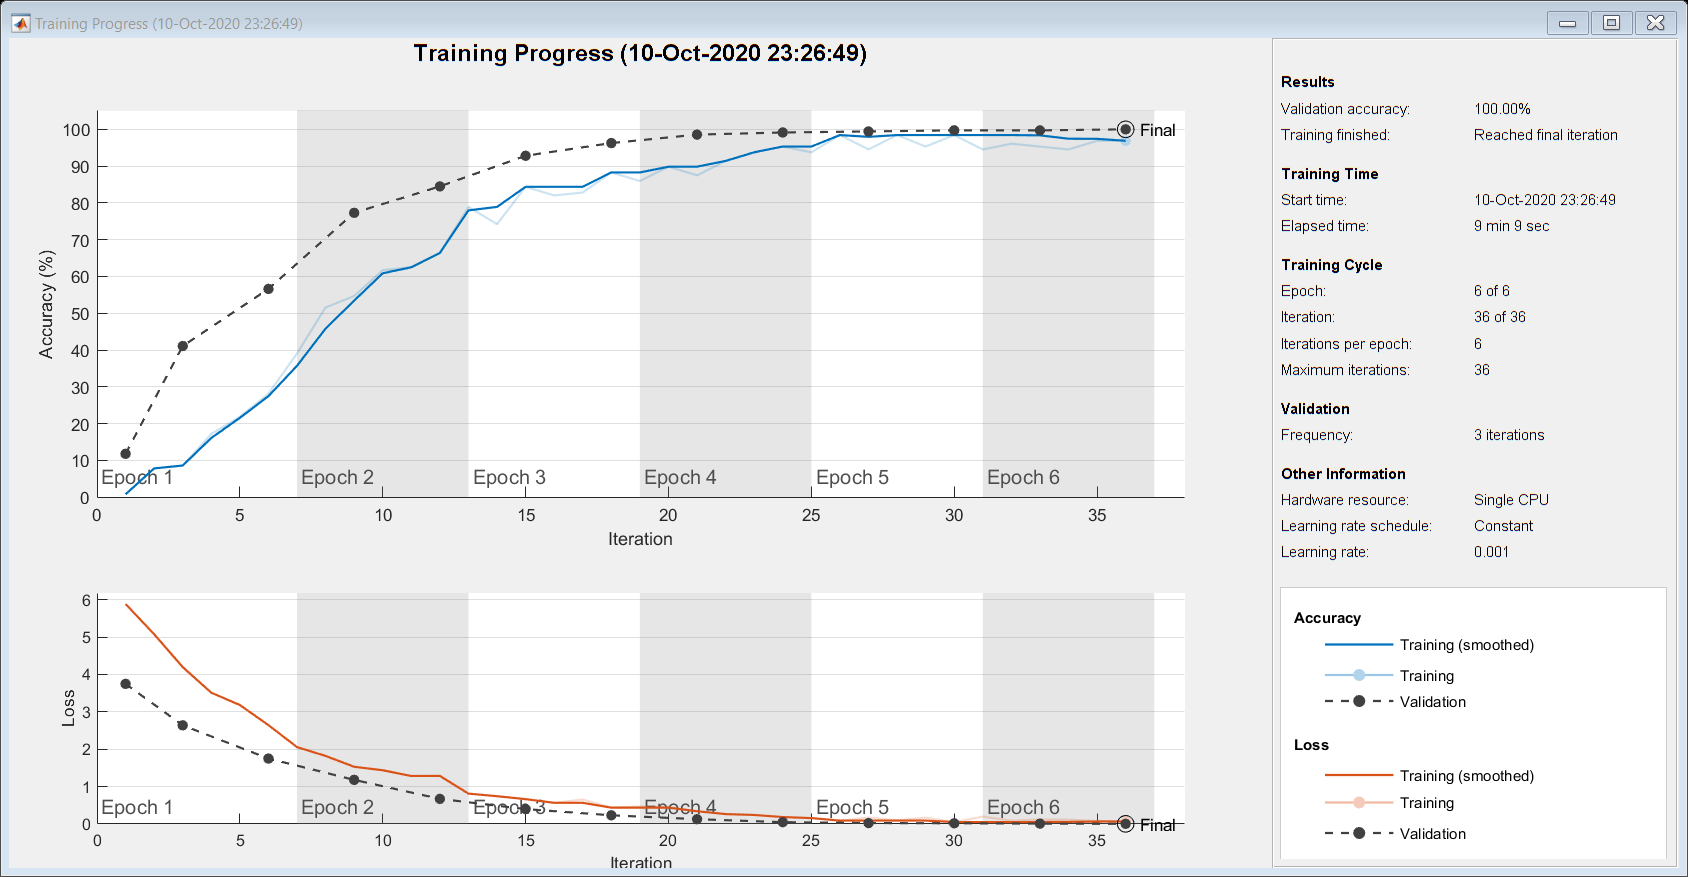

%training the new network
aslclassifier=trainNetwork(augimdstrain,flayers,opts);

save aslclassifier;

predicts=classify(aslclassifier,test_data);

Unrecognized function or variable 'aslclassifier'.